clear 
clf 

y0 = [0,0,400,0];
tspan = [0,20];
[t,y] = ode45(@rorelseekv,tspan,y0);


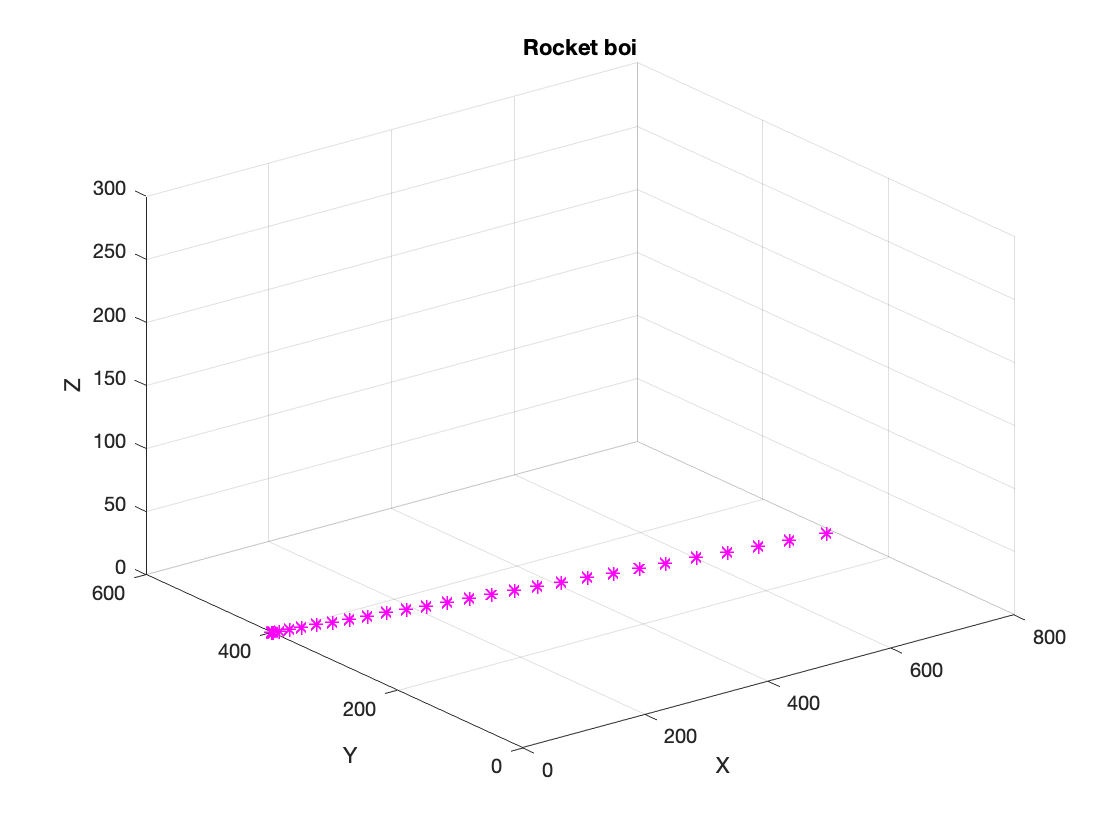

% Plot with animation 
for i=1:length(y)
    
 xlabel("X")
 ylabel("Y")
 zlabel("Z")
 title("Rocket boi")
    
 plot3(y(i,1),y(i,3),0,'*m','LineWidth',1);
 axis([0 800 0 600 0 300])
 grid on;
 hold on;
 pause(0.1);
  
end

% Plot av derivatan, dvs hastigheten
hold off 

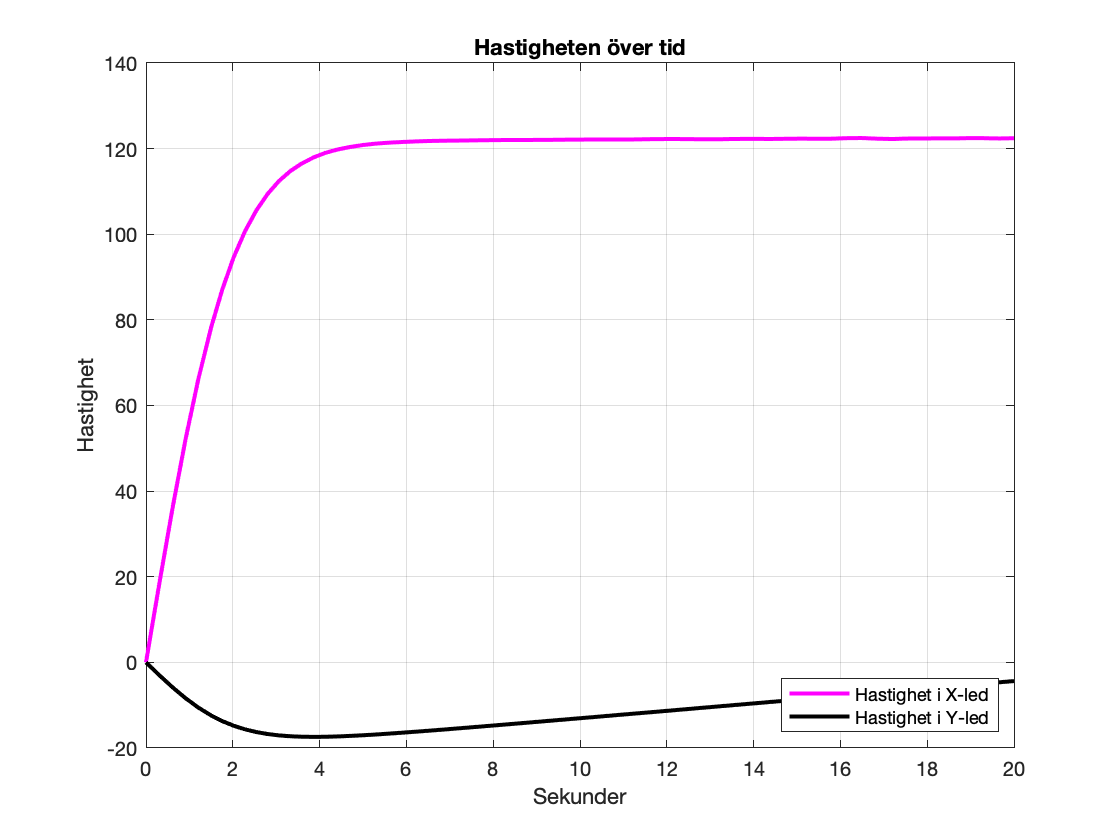

clf

plot(t,y(:,2), 'm', 'LineWidth', 2)
hold on 

grid on
xlabel("Sekunder")
ylabel("Hastighet")
title("Hastigheten över tid")

plot(t,y(:,4), 'black','LineWidth',2)
legend("Hastighet i X-led","Hastighet i Y-led")
legend('Location','southeast')

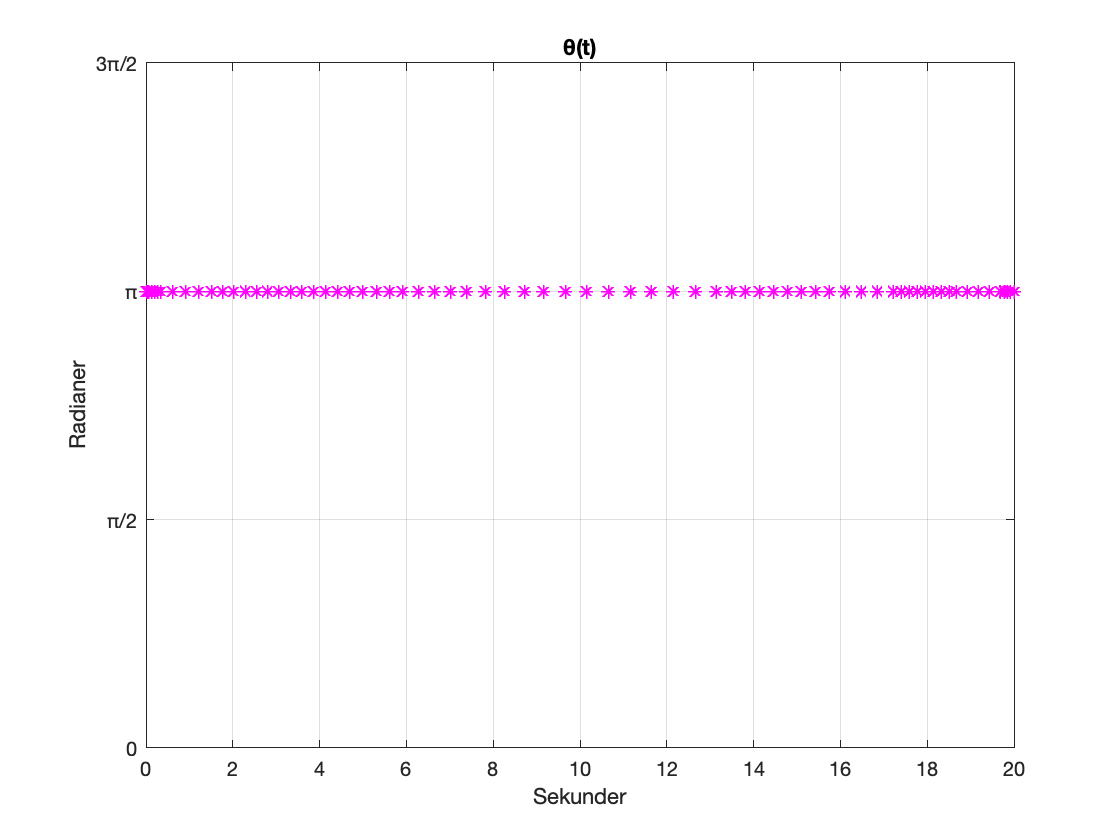

% Vinkel över tid

clf 
hold off

for i=1:length(t)
    
 plot(t,vinkel(t),'*m','LineWidth',1);
 
 grid on;
 hold on;
 pause(0.01);
 
 xlim([0,20])

 yticks([0 pi/2 pi 3*pi/2])
 yticklabels({'0','π/2','π','3π/2'})

 ylim([0 3*pi/2])

 xlabel("Sekunder")
 ylabel("Radianer")
 title("θ(t)")
  
end